# Plot Gas Prices

This interaction is not graded. You can move to the next section when you are ready.

countries = readmatrix("./data/gPrices.xlsx", "Sheet", "countries", "OutputType", "string");
prices = readmatrix("./data/gPrices.xlsx", "Sheet", "prices");
Year = readmatrix("./data/gPrices.xlsx", "Sheet", "Year");
whos

  Name            Size            Bytes  Class     Attributes

  Year           19x1               152  double              
  countries       1x10              668  string              
  prices         19x10             1520  double              



## User Input

When you create a dropdown from a vector, the default value is the first element.

Select country.

ctry = countries(1);
idxVec = strcmp(ctry, countries);
idx = find(idxVec)

idx = 1

## Price Analysis

The dropdown menu is a variable assignment, and like others, displays the output if there is no semicolon.  Since the country you selected is already visible, this is unnecessary.

Extract data for the chosen country

ctryPrices = prices(:, idx);

Make plot

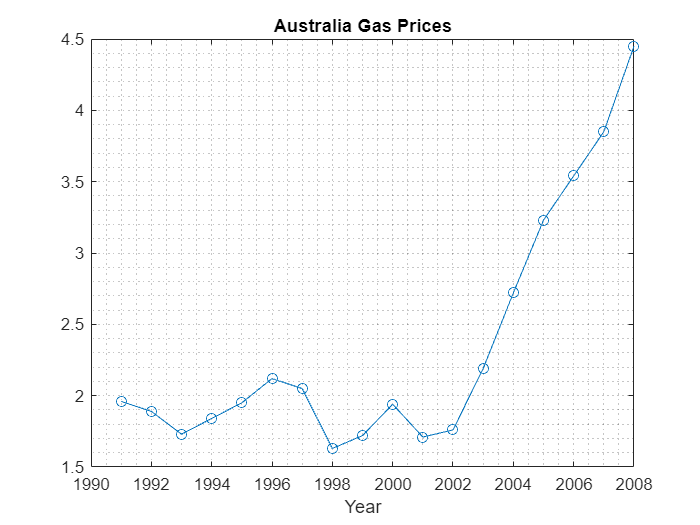

plot(Year, ctryPrices, "o-")
grid minor
xlabel("Year")
title(ctry + " Gas Prices")